# Exercise 1 - Part A

#### We want to compute the ***gain matrix***** F(k) and then validate the results by comparing *****performance index***** J with Bellman function expressed in quadratic form.**

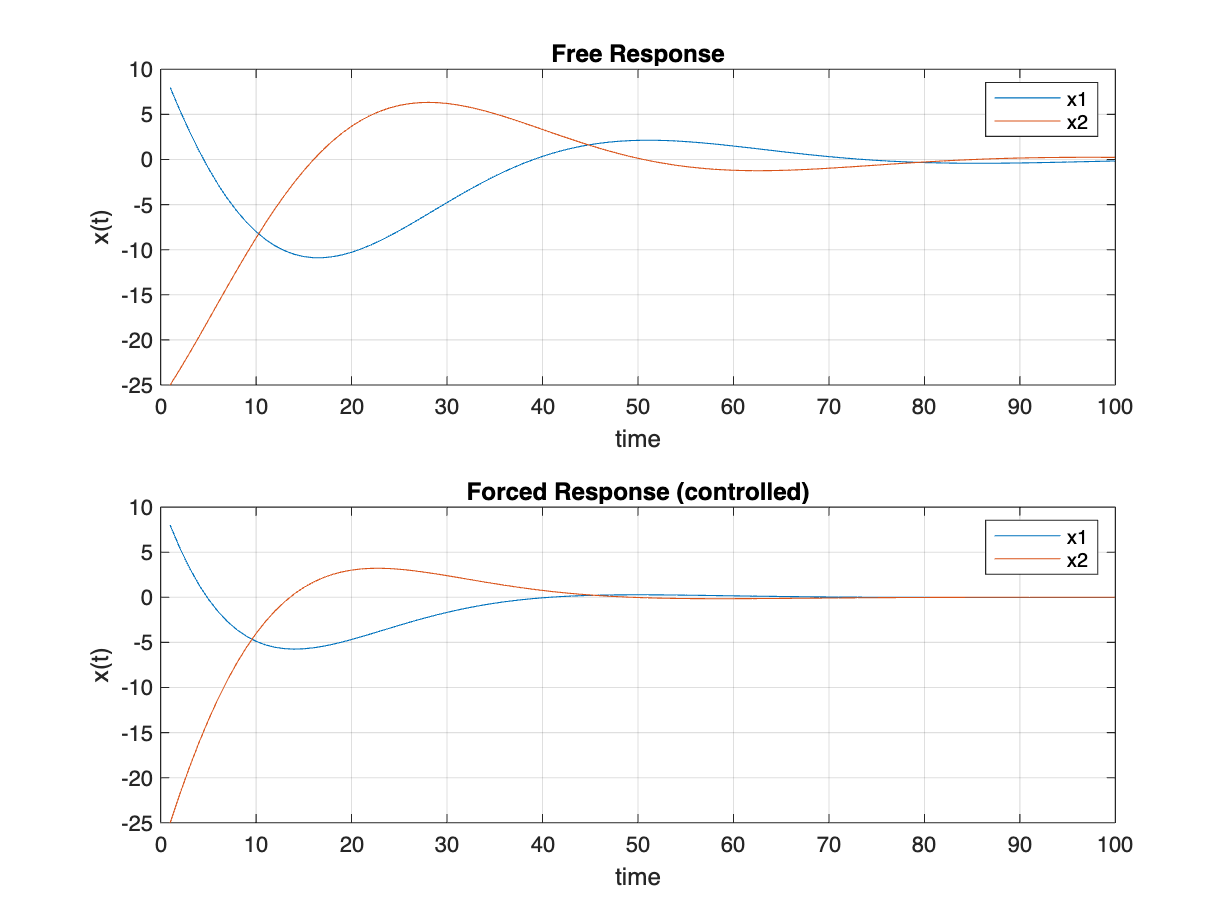

clc
clear
close all

%% Dynamical system
parameters.K=1;
parameters.M=1;
parameters.b=1;
parameters.Ts=0.1;
K=parameters.K;
M=parameters.M;
b=parameters.b;
Ts=parameters.Ts;
A=[1 Ts; -K*Ts/M 1-b*Ts/M];
B=[0; Ts/M];
clear K M b Ts
[parameters.n,parameters.m]=size(B);

%% LQR
parameters.Q=eye(parameters.n);
parameters.R=eye(parameters.M);
parameters.S=eye(parameters.n);
N=50*2;
[PP,FF]=OLQR(A,B,parameters.Q,parameters.R,parameters.S,N);

%% Simulation (free response)

x_0 = [8; -25];
x_samples = [x_0];
x_forced_samples = [x_0];

for k = 1:N-1
    x_k = A * x_samples(:,k);
    x_samples = [x_samples x_k];
    % Forced res. (controlled)
    x_k_forc = A * x_forced_samples(:,k) + B * FF{k} * x_forced_samples(:,k);
    x_forced_samples = [x_forced_samples x_k_forc];
end

% Separating state components
x1 = x_samples(1,:);
x2 = x_samples(2,:);
x1_f = x_forced_samples(1,:);
x2_f = x_forced_samples(2,:);

% Plots free and forced
figure(Name='Plots');
subplot(2,1,1);
plot(1:N, x1, 1:N, x2); 
grid on; title('Free Response'); legend('x1','x2'); xlabel('time'); ylabel('x(t)');
subplot(2,1,2);
plot(1:N, x1_f, 1:N, x2_f); 
grid on; title('Forced Response (controlled)'); legend('x1','x2'); xlabel('time'); ylabel('x(t)');

# Part B

#### We would like to validate our results by performing the following theoretical result:

#### V(t,x(t)) = min J(t,x(t),u[t,T)) = x(t)'P(t)x(t)

% Compute the vector of inputs



% Compute the right-hand side
%values = J(parameters.Q, parameters.S, parameters.R, N, x_samples, )
